# Kubo-Greenwood formula for longitudinal conductivity



clear;
col_tot = 20;
row_tot = 2;
t_x = 1;
t_y = 1;
%%
eta = 1e-1;
%%
N_Iteration = 70;

Tr = 1;
Disorder = 0;
ave = 1;

Hamiltonian = get_Nearest_Square_Hopping_Sparse(col_tot, row_tot, t_x, t_y);
Eigen = eig(Hamiltonian);
% Hamiltonian = Hamiltonian + Disorder * sprand(speye(size(Hamiltonian))-0.5);

x_operator = sparse(kron(diag(1:col_tot),eye(row_tot)));
velocity_operator_x = 1i * (Hamiltonian * x_operator - x_operator * Hamiltonian);

% 端口哈密顿量
H_Metal_Lead = - t_y * diag(ones(row_tot-1,1),-1) - t_y * diag(ones(row_tot-1,1),+1);
V_Metal_Lead = - t_x * eye(row_tot);


omega = -4:0.01:4;
transmission = zeros(ave, length(omega));
tic;
Sigma_Extend = zeros(size(Hamiltonian));

    for ii = 1:length(omega)
        for jj = 1:ave
            % G_00_Left = SurfaceGreenFunction(H_Metal_Lead, V_Metal_Lead, omega(ii), N_Iteration);
            % G_00_Right = SurfaceGreenFunction(H_Metal_Lead, V_Metal_Lead', omega(ii), N_Iteration);
            % 
            % Sigma_Extend(1:row_tot, 1:row_tot) = SurfaceGreenFunction_SelfEnergy(G_00_Left, Tr * V_Metal_Lead);
            % Sigma_Extend(end-row_tot+1:end, end-row_tot+1:end) = SurfaceGreenFunction_SelfEnergy(G_00_Right, Tr * V_Metal_Lead);
            GreenFun = ((omega(ii) + 1i * eta) * speye(size(Hamiltonian)) - Hamiltonian- (Disorder * sprand(speye(size(Hamiltonian))-0.5)))\ speye(size(Hamiltonian));
            transmission(jj,ii) = real(trace( imag(GreenFun)* velocity_operator_x* imag(GreenFun) * velocity_operator_x ));
        end
    end
toc;

历时 0.532710 秒。


Tem = 0.01;
Trans_Tem = zeros(1,length(omega));
for ii = 1:length(omega) 
    if ave == 1
        Trans_Tem(ii) = FiniteTemperatureTransmission(omega, transmission, omega(ii), Tem);
    else
        Trans_Tem(ii) = FiniteTemperatureTransmission(omega, mean(transmission,1), omega(ii), Tem);
    end
end

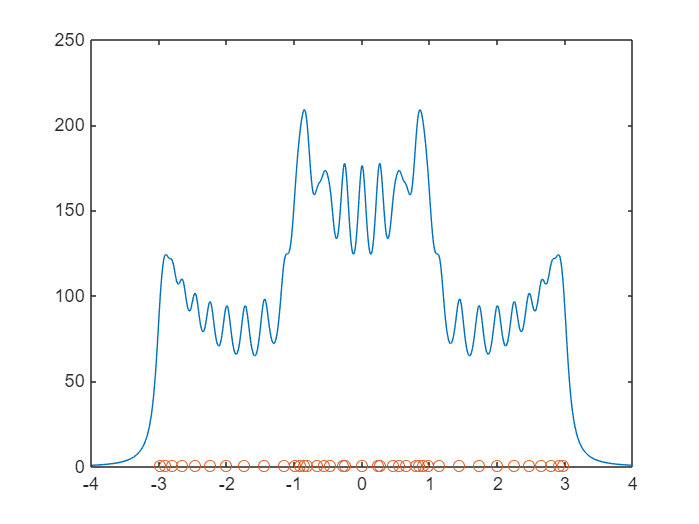


plot(omega, mean(transmission,1), Eigen, 0.5*ones(1,length(Eigen)),'o')

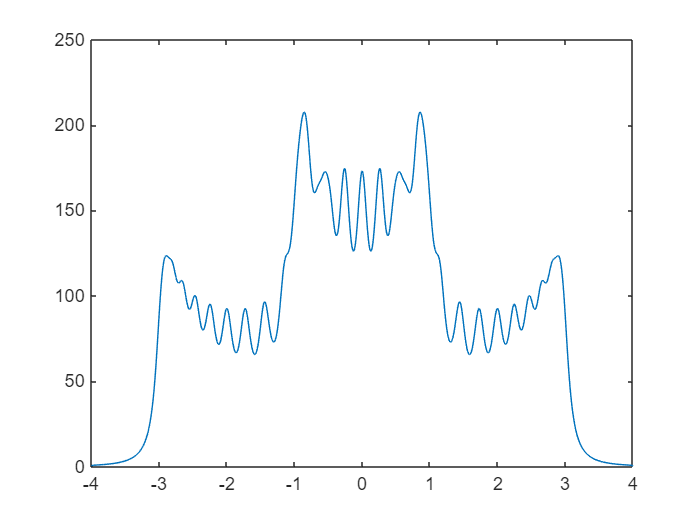

plot(omega, Trans_Tem)

% axis([-4,4,0,1.2])